fprintf('please Select an image');

please Select an image

y=uigetfile('*.*');
i=imread(y);
k=rgb2gray(i);
d = padarray(k,[1 1],0,'both');
[r,c]=size(d);
s=zeros(r+2,c+2)

s =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

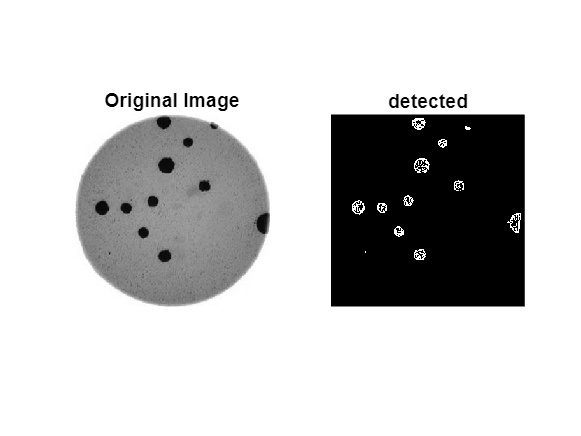

for R =2:(r-1)
   for C=2:(c-1)
      s(R,C)= d(R+1,C)+d(R-1,C)+d(R,C+1)+d(R,C-1)-4*d(R,C);
%         if value>=100
%             d(R,C)=1;
%         else
%             d(R,C)=0;
%         end
   end
end

subplot(1,2,1);imshow(k);title('Original Image');
subplot(1,2,2);imshow(s);title('detected');